# Mohammadreza Arani

## COnvex Optimization

## 810100511

% Hw7 - Q-->5
clear; clc; close all;

% Load Random Data:
m = 100;
n = 500;

A= rand(m,n) ; 
c= rand(n,1);
x_0 = rand(n,1);

b = A*x_0;


[x_star, V_opt, Lambdas , iter] = Newton_method_q5(A,b,c,x_0);

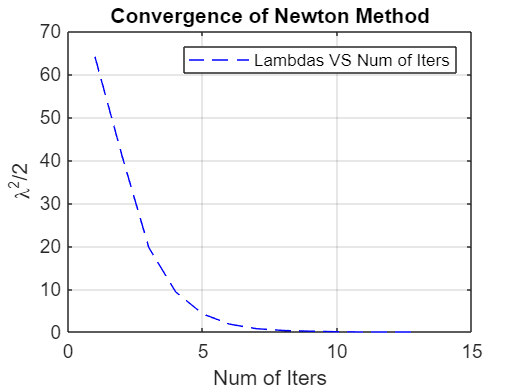

% Plot the results:
figure()
plot(1:iter,Lambdas,'b--')
legend('Lambdas VS Num of Iters');
xlabel('Num of Iters');
ylabel('\lambda^2/2');
title('Convergence of Newton Method')
grid on;

disp('V_opt is : ')

V_opt is : 


disp(V_opt')

  Columns 1 through 6

  -0.022972992172156   0.257392243649177   0.114638436870183  -0.002589169657851  -0.109980334448393   0.026839052387396

  Columns 7 through 12

   0.257679940330713  -0.140169538478114   0.264311513257759  -0.087705164013871  -0.032318180523530   0.125154134511750

  Columns 13 through 18

   0.377491684303493   0.063362124591734   0.161473918900203   0.018474268663239  -0.177799439135262  -0.135424805133456

  Columns 19 through 24

   0.107213895530140   0.022124115346377   0.303507150816960   0.034079131366690  -0.333956166533571  -0.083784981749335

  Columns 25 through 30

  -0.049913244918483  -0.087630915780140   0.097562365901992   0.051828399505774  -0.055929477978337   0.312813878374937

  Columns 31 through 36

  -0.075407065255637   0.349011181928543  -0.147268442636593  -0.119668152607210   0.099434442796308   0.201728083307284

  Columns 37 through 42

   0.178021083552687   0.254718066811186   0.358486086496091   0.154487241015060   0.03626479203

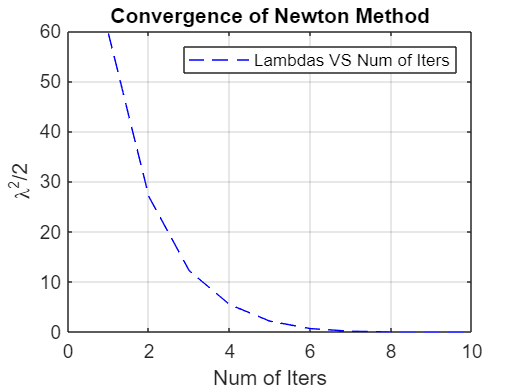

% Another random point:
A= rand(m,n) ; 
c= rand(n,1);
x_0 = rand(n,1);

b = A*x_0;
[x_star2, V_opt2, Lambdas2 , iter2] = Newton_method_q5(A,b,c,x_0);
% Plot the results:
figure()
plot(1:iter2,Lambdas2,'b--')
legend('Lambdas VS Num of Iters');
xlabel('Num of Iters');
ylabel('\lambda^2/2');
title('Convergence of Newton Method')
grid on;

% Using KKT System:

[x_star3, V_opt3, Lambdas3, iter3] = Newton_method_q5_KKT(A,b,c,x_0)

x_star3 =    0.580950884106911
   0.384919681597391
   0.621084744126251
   0.910334217433320
   0.695994006660801
   0.493436305558372
   0.454076261860091
   0.346822559183342
   0.905628874456968
   0.334332236621497


V_opt3 =   -0.001279949180280
   0.564618811769372
   0.081422214132736
   0.378430335227760
   0.248812682551641
   0.151601646521170
  -0.011121959055077
   0.157025615350592
  -0.190430797466370
  -0.182561414405442


Lambdas3 =   59.522971167459261  27.008351415366697  12.226089457588960   5.470696575491893   2.153249922631308   0.680284730978575   0.149282652592947   0.012895573329120   0.000107955293304   0.000000009306786


iter3 =     10


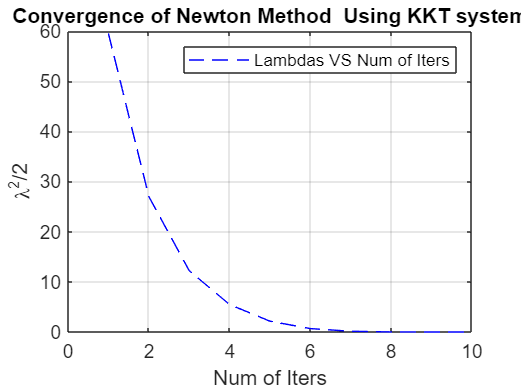

figure()
plot(1:iter2,Lambdas2,'b--')
legend('Lambdas VS Num of Iters');
xlabel('Num of Iters');
ylabel('\lambda^2/2');
title('Convergence of Newton Method  Using KKT system')
grid on;

function [x_star, V_opt, Lambdas, iter] = Newton_method_q5_KKT(A,b,c,x_0)


    max_Count = 100;
    m = length(b);
    n = length(x_0);
    x = x_0; 
    Lambdas = [];
    alpha = 0.01;
    beta = 0.5;
    eps = 10^-6;


    if (min(x_0) <= 0) || (norm(A*x_0 - b) > 1e-3) % check feasibility of x_0
        fprintf('Not Feasible');
        V_opt = []; x_star = []; Lambdas=[];
        return;
    end

for iter = 1:max_Count

    H = diag(x.^(-2));
    g = c - x.^(-1);


% Newton step via whole KKT system
        M = [ H A'; A zeros(m,m)];
        d = M\[-g; zeros(m,1)];
        dx = d(1:n);
        w = d(n+1:end);


    lambdasqr = -g'*dx;          % dx'*H*dx;
    Lambdas = [Lambdas lambdasqr/2];


    if lambdasqr/2 <= eps 
        break;
    end


    % backtracking line search
    % first bring the point inside the domainTheta
    t = 1; 
    while min(x+t*dx) <= 0
        t = beta*t; 
    end

    % Backtracking line search:
        while c'*(t*dx)-sum(log(x+t*dx))+sum(log(x))-alpha*t*g'*dx> 0
            t = beta*t;
            end
            x = x + t*dx;
 end

    if iter == max_Count % max_Count reached
        disp('Did not Coverged!');
        x_star = []; V_opt = [];
        else
        x_star = x;
        V_opt = w;
    end

end
%%

function [x_star, V_opt, Lambdas, iter] = Newton_method_q5(A,b,c,x_0)


    max_Count = 100;
    m = length(b);
    n = length(x_0);
    x = x_0; 
    Lambdas = [];
    alpha = 0.01;
    beta = 0.5;
    eps = 10^-6;


    if (min(x_0) <= 0) || (norm(A*x_0 - b) > 1e-3) % check feasibility of x_0
        fprintf('Not Feasible');
        V_opt = []; x_star = []; Lambdas=[];
        return;
    end

for iter = 1:max_Count

    H = diag(x.^(-2));
    g = c - x.^(-1);


% Newton step via whole KKT system
        % M = [ H A'; A zeros(m,m)];
        % d = M\[-g; zeros(m,1)];
        % dx = d(1:n);
        % w = d(n+1:end);

    % Newton Step by elimination method
    w = (A*diag(x.^2)*A')\(-A*diag(x.^2)*g);
    dx = -diag(x.^2)*(A'*w + g);
    lambdasqr = -g'*dx;          % dx'*H*dx;
    Lambdas = [Lambdas lambdasqr/2];


    if lambdasqr/2 <= eps 
        break;
    end


    % backtracking line search
    % first bring the point inside the domainTheta
    t = 1; 
    while min(x+t*dx) <= 0
        t = beta*t; 
    end

    % Backtracking line search:
        while c'*(t*dx)-sum(log(x+t*dx))+sum(log(x))-alpha*t*g'*dx> 0
            t = beta*t;
            end
            x = x + t*dx;
 end

    if iter == max_Count % max_Count reached
        disp('Did not Coverged!');
        x_star = []; V_opt = [];
        else
        x_star = x;
        V_opt = w;
    end

end